# Day Analyze

**目的：**对比well trained与critical day之间的差别

**现象：**well train 阶段neuron和event之间的互信息更大，但之前阶段neuron之间的互信息更大，而且组合较为固定

**结论：**选取critical day应该能获得更好的预测结果

close all;clear;clc;

## Analyze rat_010_07_04(well trained)

[M1, mPFC, ratios, eventTrain] = spikeTime2Train("data/rat_010_07_04.mat");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
    'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.1314
mPFCwithSpike=0.0976
M1multiSpike=0.0499
mPFCmultiSpike=0.0402

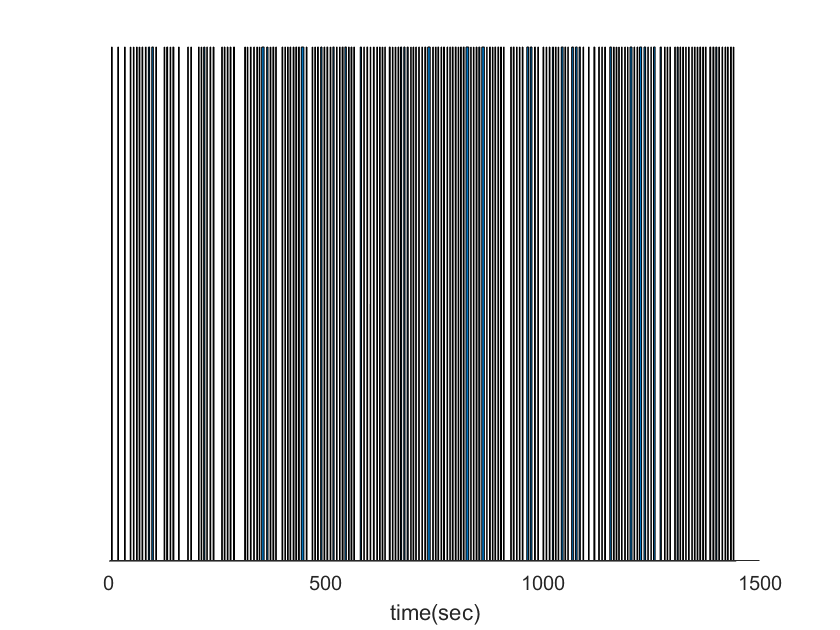

spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

event during 570.01s~910s seems continuously repeated. take for futher work.

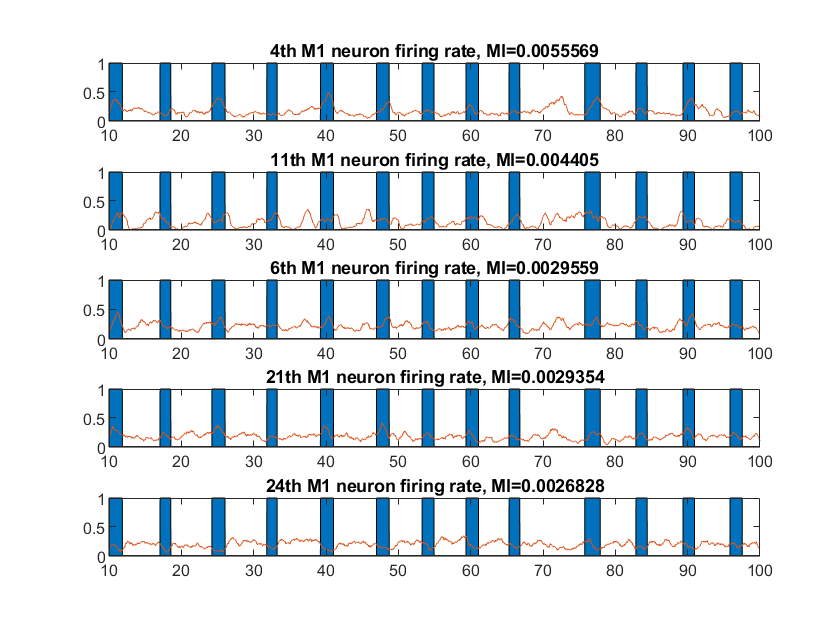

takenBins = 57001:91000;
spikeLength = length(takenBins);
eventTrain = eventTrain(takenBins)';
mPFC = mPFC(takenBins,:);
M1 = M1(takenBins,:);

emMI = mutualInformation(eventTrain, M1);
epMI = mutualInformation(eventTrain, mPFC);
nMI  = mutualInformation(M1, mPFC);

[mi, eM1index] = sort(emMI, 'descend');
t=10:0.01:100;
bins = 1000:10000;
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(M1(bins, eM1index(i)), 50))
  hold off
  title([num2str(eM1index(i)), 'th M1 neuron firing rate, MI=', num2str(mi(i))])
end

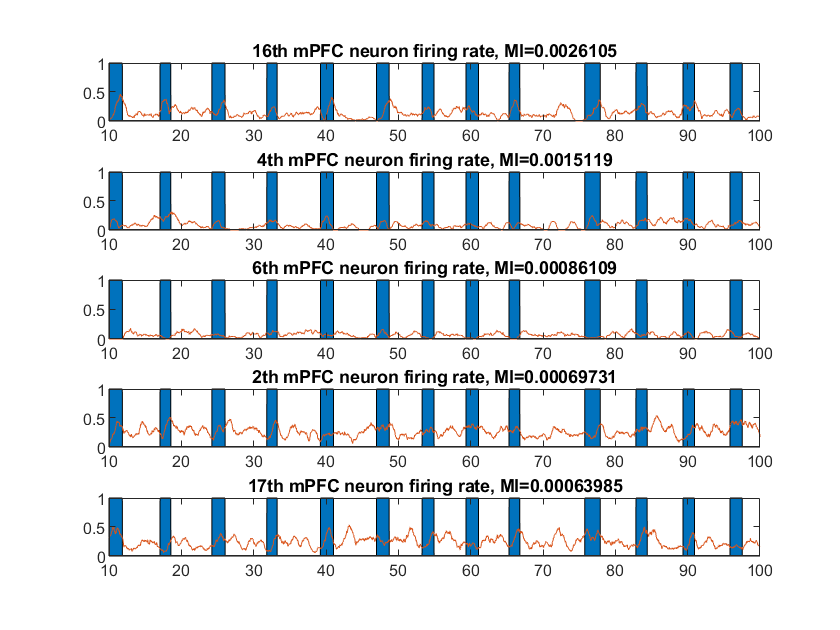

[mi, emPFCindex] = sort(epMI, 'descend');
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, emPFCindex(i))*2, 50))
  hold off
  title([num2str(emPFCindex(i)), 'th mPFC neuron firing rate, MI=', num2str(mi(i))])
end

与event互信息前五的neuron之间的互信息

nMI(eM1index(1:5), emPFCindex(1:5))

ans = 	1.0e+-3 *

    0.2139    0.1778    0.1078    0.0000    0.4347
    0.1339    0.0123    0.0972    0.0486    0.0009
    0.0147    0.0002    0.0481    0.0201    0.0138
    0.1829    0.0789    0.4346    0.1278    0.2418
    0.0471    0.0026    0.0187    0.0270    0.0056


event-M1前五对应的五个mPFC

[mi, mPFCindex] = sort(nMI(eM1index(1:5),:), 2, 'descend');
disp(num2str(mPFCindex(:, 1:5)))

17  16  14   4  12
16   1  20  10  23
 1  13  23  22  11
 6  17  10  16  14
19  22  15  13  10


以及他们的互信息

mi(:, 1:5)

ans = 	1.0e+-3 *

    0.4347    0.2139    0.1932    0.1778    0.1648
    0.1339    0.1304    0.1252    0.1139    0.1117
    0.2527    0.1227    0.0820    0.0563    0.0556
    0.4346    0.2418    0.1958    0.1829    0.1328
    0.1336    0.0927    0.0552    0.0524    0.0510


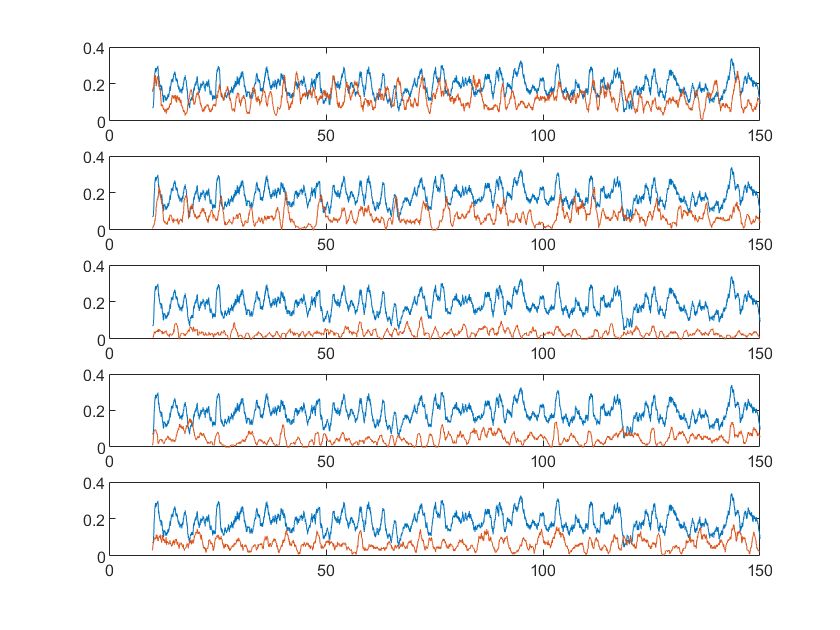

t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, 7), 50))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(1,i)), 50))
  hold off
end

## Analyze rat010_0615(critical day)

close all;clear;clc;
[M1, mPFC, ratios, eventTrain] = spikeTime2Train("data/data_rat010_0615_event");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
    'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.2069
mPFCwithSpike=0.1322
M1multiSpike=0.1154
mPFCmultiSpike=0.0669

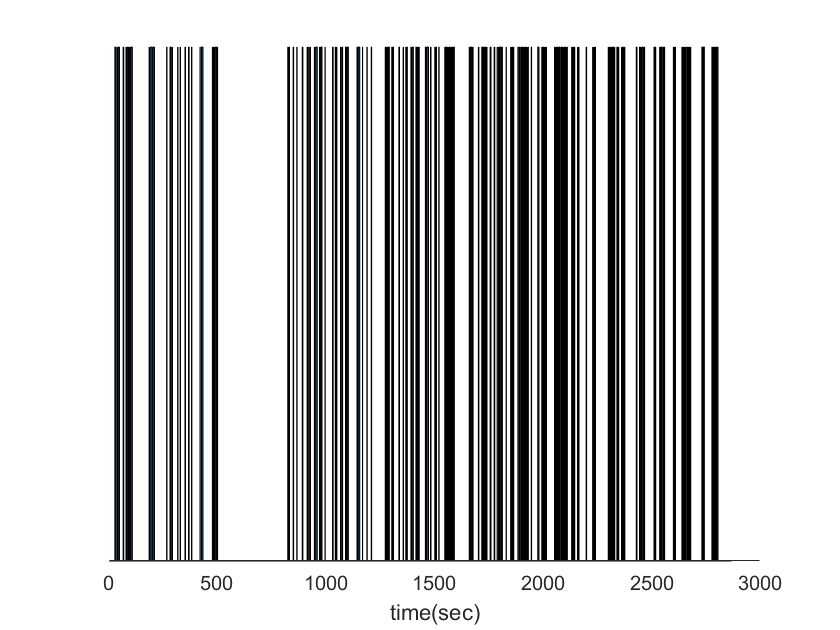

spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

event during 820.01s~1600s seems continuously repeated. take for futher work.

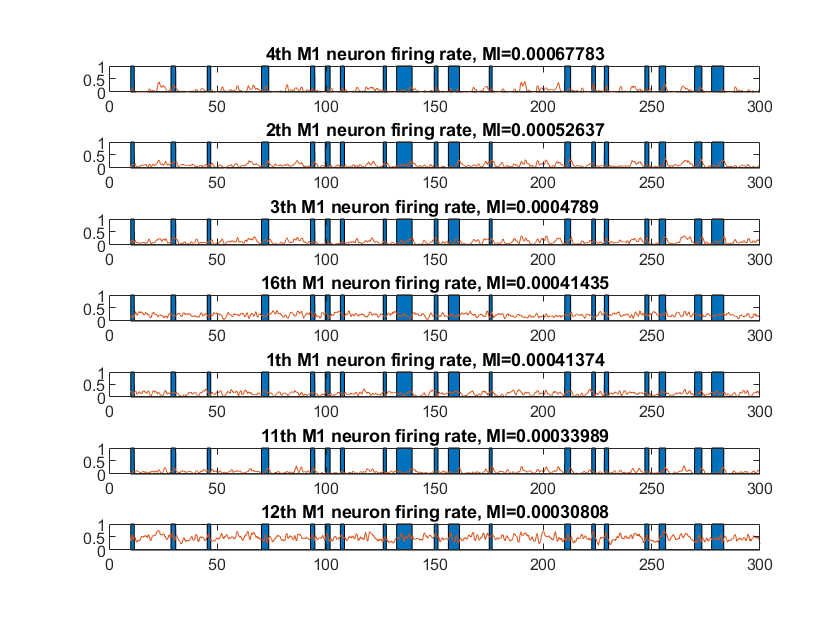

takenBins = 82001:160000;
spikeLength = length(takenBins);
eventTrain = eventTrain(takenBins)';
mPFC = mPFC(takenBins,:);
M1 = M1(takenBins,:);

emMI = mutualInformation(eventTrain, M1);
epMI = mutualInformation(eventTrain, mPFC);
nMI  = mutualInformation(M1, mPFC);

[mi, eM1index] = sort(emMI, 'descend');
t=10:0.01:300;
bins = 1000:30000;
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:7
  subplot(7,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(M1(bins, eM1index(i)), 50))
  hold off
  title([num2str(eM1index(i)), 'th M1 neuron firing rate, MI=', num2str(mi(i))])
end

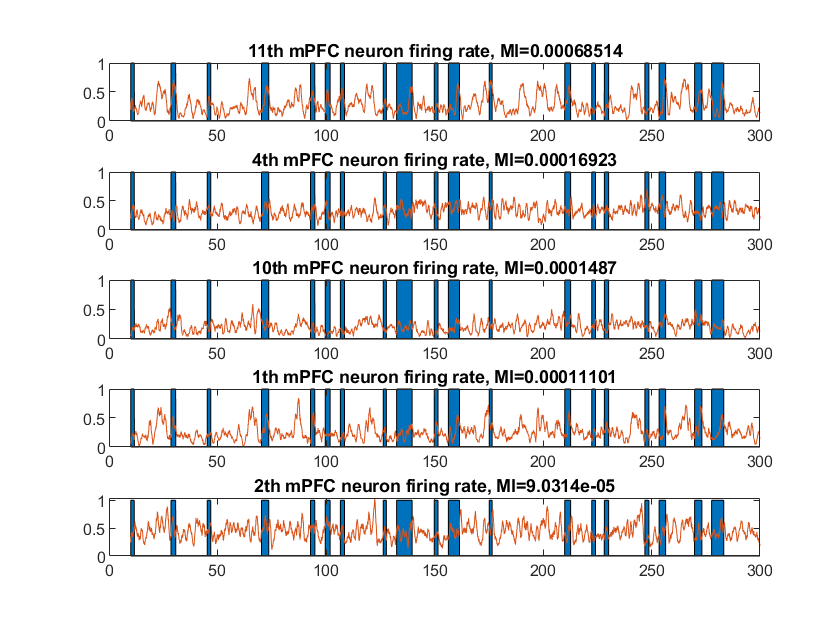

[mi, emPFCindex] = sort(epMI, 'descend');
figure
% subplot(6,1,1)
% area(t, eventTrain(bins))
% set(gca, 'TickLength', [0 0])
% set(gca, 'ytick', [])
% set(gca, 'box', 'off')
% set(gca, 'YColor', 'white')
% xlabel("time(sec)")
for i=1:5
  subplot(5,1,i)
  area(t, eventTrain(bins))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, emPFCindex(i))*2, 50))
  hold off
  title([num2str(emPFCindex(i)), 'th mPFC neuron firing rate, MI=', num2str(mi(i))])
end

与event互信息前五的neuron之间的互信息

nMI(eM1index(1:5), emPFCindex(1:5))

ans =     0.0008    0.0000    0.0002    0.0013    0.0003
    0.0010    0.0001    0.0004    0.0016    0.0005
    0.0008    0.0002    0.0003    0.0015    0.0004
    0.0000    0.0001    0.0003    0.0001    0.0000
    0.0002    0.0001    0.0001    0.0004    0.0001


event-M1前五对应的五个mPFC

[mi, mPFCindex] = sort(nMI(eM1index(1:5),:), 2, 'descend');
disp(num2str(mPFCindex(:, 1:8)))

1   7  11   8   5   2  12   6
7   8   5   1   6  13  11  12
7   8   5   1   6  13  11   3
7   8  13   6   9   5  10   3
7   6   5  13   8   1   3  12


以及他们的互信息

mi(:, 1:8)

ans =     0.0013    0.0012    0.0008    0.0007    0.0005    0.0003    0.0002    0.0002
    0.0053    0.0027    0.0026    0.0016    0.0016    0.0014    0.0010    0.0010
    0.0039    0.0028    0.0017    0.0015    0.0011    0.0009    0.0008    0.0006
    0.0015    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0001
    0.0027    0.0010    0.0010    0.0010    0.0009    0.0004    0.0003    0.0002


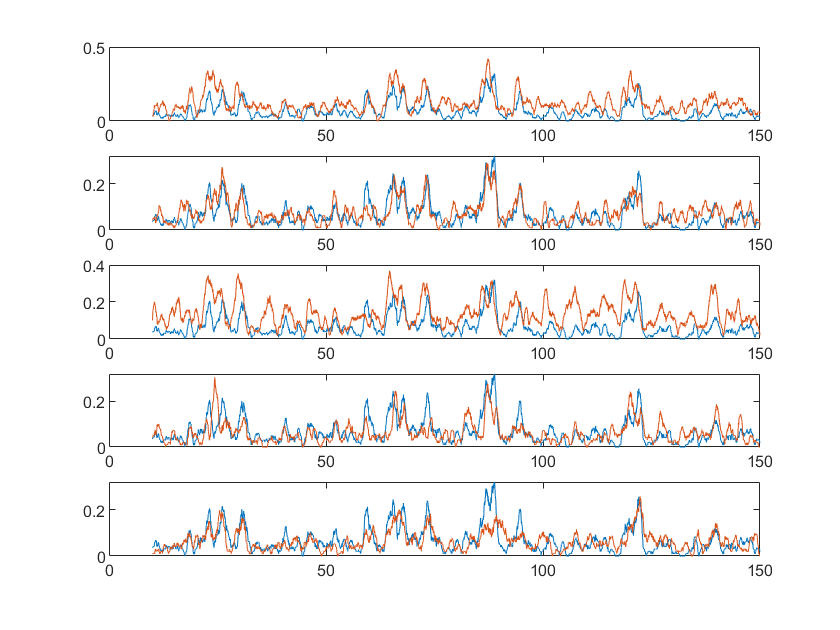

t=10:0.01:150;
bins = 1000:15000;
figure
for i=1:5
  subplot(5,1,i)
  plot(t, gaussianSmooth(M1(bins, 7), 50))
  hold on
  plot(t, gaussianSmooth(mPFC(bins, mPFCindex(1,i)), 50))
  hold off
end

可以看出在critical day的mPFC与M1的联系似乎更为紧密，因此选取其中部分数据来跑模型

依然选取其中mutual information比较大的来做数据集，mPFC的数量是自己估计的

M1neurons   = [7 11 17];
mPFCneurons = [5 6 7 8 13];
M1spike = M1(:, M1neurons);
mPFCspike = mPFC(:, mPFCneurons);
% save("data/data_rat010_0615_spike_train_selected.mat", "M1spike", "mPFCspike", "eventTrain")